function [data, labels] = generate_synthetic_eeg(T, N, fs)

t = (0:T-1)/fs;

data = zeros(2, T, N);
labels = zeros(N,1);

for i = 1:N
    
    % Random class
    if i <= N/3
        cls = 0; % rest
    elseif i <= 2*N/3
        cls = 1; %right hand
    else
        cls = -1; %left hand
    end

    labels(i) = cls;
    
    % Base noise
    X = 0.5 * randn(2, T);
    
    for ch = 3:4
        
        % μ rhythm (10 Hz)
        mu_wave = sin(2*pi*10*t);
        
        % β rhythm (20 Hz)
        beta_wave = sin(2*pi*20*t);
        
        if cls == 0
            % REST → strong mu
            signal = 1.5 * mu_wave + 0.5 * beta_wave;
        elseif (cls == 1)
            % HAND right→ mu suppressed (ERD)
            signal = 0.5 * mu_wave + (2*(ch == 3) + 1*(ch == 4)) * 1.0 * beta_wave;
        else 
            % HAND left→ mu suppressed (ERD)
            signal = 0.5 * mu_wave + (1*(ch == 3) + 2*(ch == 4)) * 1.0 * beta_wave;
        end
        
        % Only inject strongly in motor channels
        X(ch-2,:) = X(ch-2,:) + signal;
        
    end
    
    % % Add slight spatial mixing
    % mix = randn(2);
    % % Add noise 
    % mix = eye(2) + 0.2*randn(2); % small mixing only
    % X = mix * X;
    
    data(:,:,i) = X;
end

end


[dd , ll] = generate_synthetic_eeg(1000,90,2000);
[testdd, testll] =  generate_synthetic_eeg(1000,3,2000);

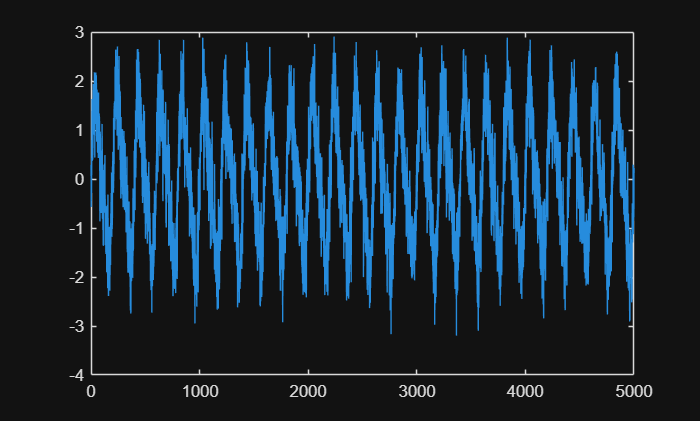



plot([dd(1,:,1),dd(1,:,2),dd(1,:,3),dd(1,:,4),dd(1,:,5)]);

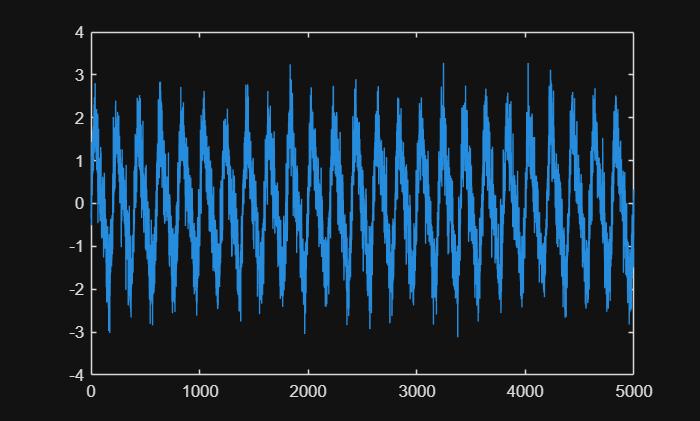

plot([dd(2,:,1),dd(2,:,2),dd(2,:,3),dd(2,:,4),dd(2,:,5)]);

ll

ll =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


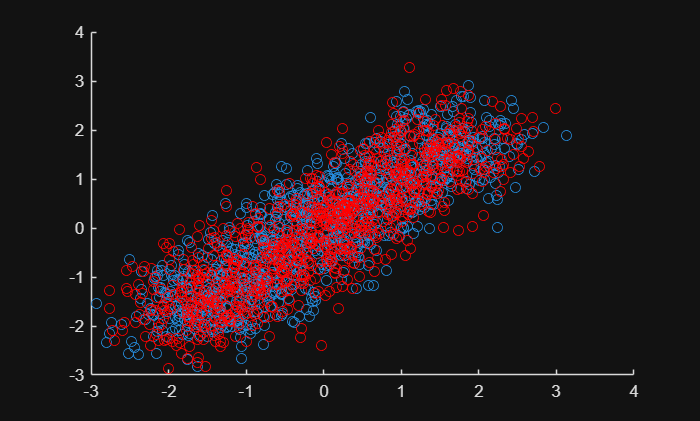

figure;
scatter(dd(1,:,7),dd(2,:,7));
hold on;
scatter(dd(1,:,18),dd(2,:,18),'r');
hold off;

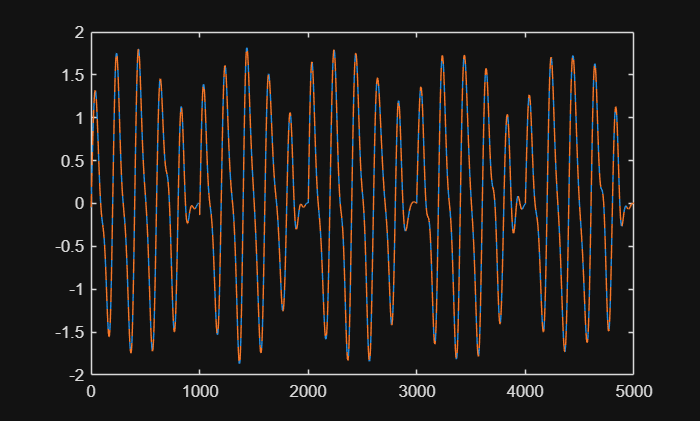

% data: [C x T x N]
% labels: [N x 1]

% Example dummy (replace with real EEG)
C = 2; T = 1000; N = 20;
% data = randn(C, T, N);
% labels = [zeros(N/2,1); ones(N/2,1)];
data = dd;
labels = ll;
fs = 2000;

% =========================
% 1. Bandpass Filter
% =========================
data_filt = bandpass_filter(data, fs, 8, 30);

figure;

plot([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)]);
hold on;
plot([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)],'--');

fdat = fft([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)],1024);

hold off;

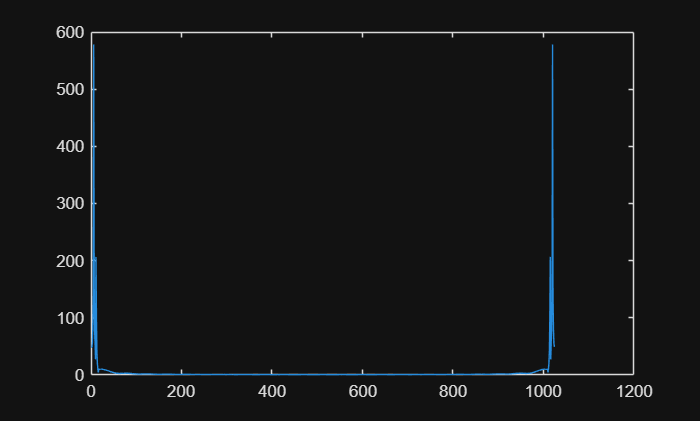

plot(abs(fdat));

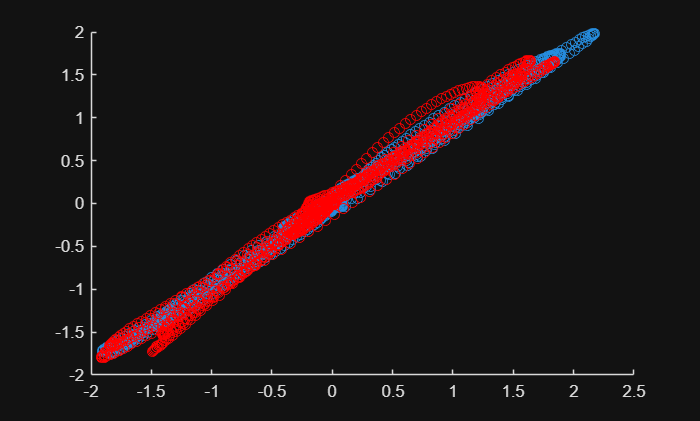

% xlim([0 50])

scatter(data_filt(1,:,8),data_filt(2,:,8));
hold on;
scatter(data_filt(1,:,15),data_filt(2,:,15),'r');
hold off;

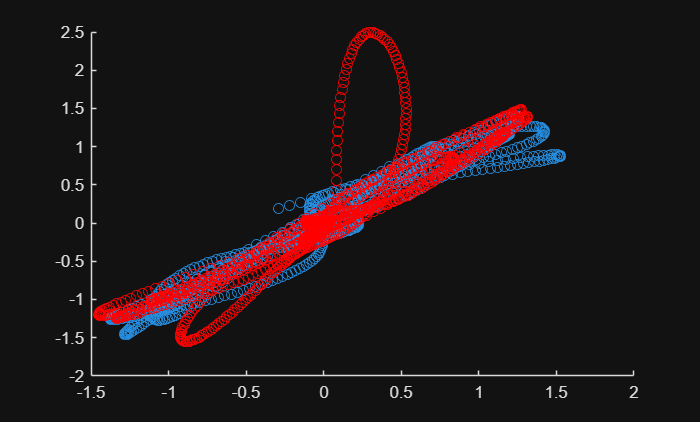


% =========================
% 2. CSP
% =========================
a(:,:,1) = data_filt(:,:,7);
a(:,:,2) = data_filt(:,:,14);  
W = compute_csp(data_filt, labels,1,-1);
Wright = compute_csp(data_filt, labels,1,0);
Wleft = compute_csp(data_filt, labels,-1,0);

csp_data = W * data_filt(:,:,12);
csp_data2 = W * data_filt(:,:,19);

figure;
scatter(csp_data(1,:),csp_data(2,:));
hold on;
scatter(csp_data2(1,:),csp_data2(2,:),'r');
hold off;

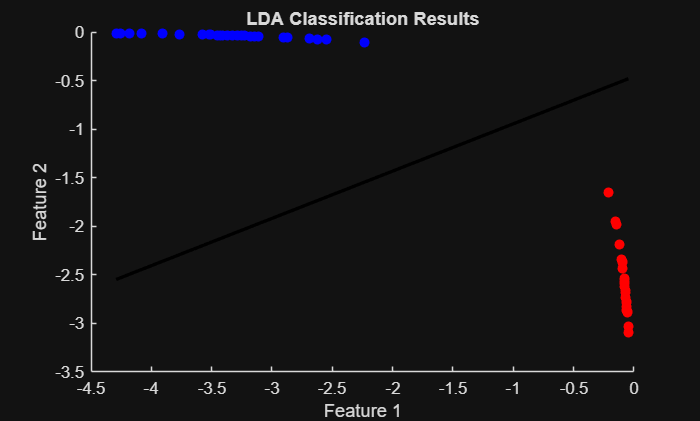


% Select few filters (important)
% m = 2;
% Wcsp = [W(:,1:m), W(:,end-m+1:end)];

% =========================
% 3. Feature Extraction
% =========================
X = extract_features(data_filt, W,Wleft,Wright,2);
X = X';
% =========================
% 4. Train LDA
% =========================
modelrightleft = myLDA_train(X(:,1:2), labels,1,-1);
modelrightrest = myLDA_train(X(:,5:6), labels,1,0);
modelleftrest = myLDA_train(X(:,3:4), labels,-1,0);

% Visualize predictions
figure;
scatter(X((ll == 1), 5), X((ll == 1),  6), 'r', 'filled');
hold on;
scatter(X((ll == 0),  5), X((ll == 0), 6), 'b', 'filled');
% scatter(X(y_pred == 0, 1), X(y_pred == 0, 2), 'x', 'MarkerEdgeColor', 'k');
% scatter(X(y_pred == 1, 1), X(y_pred == 1, 2), 'x', 'MarkerEdgeColor', 'g');
% Extract parameters
w = modelrightrest.w;
b = modelrightrest.b;

% Create line
x1_vals = linspace(min(X(:,5)), max(X(:,5)), 100);

x2_vals = -(w(1)*x1_vals + b) / w(2);

% Plot decision boundary
plot(x1_vals, x2_vals, 'k-', 'LineWidth', 2);

%legend('Class 0', 'Class 1', 'LDA Boundary');
xlabel('Feature 1');
ylabel('Feature 2');
title('LDA Decision Boundary');
%legend('Class 0', 'Class 1');
title('LDA Classification Results');
hold off;


% =========================
% 5. Predict
% =========================
y_pred = myLDA_predict(X,modelrightleft,modelleftrest,modelrightrest);

acc = mean(y_pred == labels)

acc = 1

disp(['Accuracy: ', num2str(acc)]);

Accuracy: 1


%testing model on artifical data
testfilt = bandpass_filter(testdd, fs, 8, 30);

test_feature = extract_features(testfilt, W,Wleft,Wright,2);

y_pred_test = myLDA_predict(test_feature,modelrightleft,modelleftrest,modelrightrest);

acc2 = mean(y_pred_test == testll)

acc2 = 1

disp(['Accuracy: ', num2str(acc2)]);

Accuracy: 1



function data_filt = bandpass_filter(data, fs, f_low, f_high)

[C,T,N] = size(data);
data_filt = zeros(size(data));

[b,a] = butter(4, [f_low f_high]/(fs/2), 'bandpass');

for i = 1:N
    for ch = 1:C
        data_filt(ch,:,i) = filtfilt(b, a, data(ch,:,i));
    end
end

end

% function W = compute_csp(data, labels)
% 
% [C,~,N] = size(data);
% 
% % Separate classes
% class1 = find(labels == 0);
% class2 = find(labels == -1);
% class3 = find(labels == 1);
% class4 = [class2,class3];
% 
% % Covariance matrices
% cov2 = zeros(C,C,length(class2));
% cov3 = zeros(C,C,length(class3));
% cov1 = zeros(C,C,length(class1));
% cov4 = zeros(C,C,length(class4));
% 
% k = 1;
% for i = class2'
%     X = squeeze(data(:,:,i));
%     X = X - mean(X,2); % zero-mean
%     cov2(:,:,k) =(X*X') / trace(X*X');
%     k = k + 1;
%  end
% % X = data(:,:,1);
% % X = X - mean(X,2); % zero-mean
% % cov2 = cov2 + (X*X') / trace(X*X');
% k = 1;
% for i = class3'
%     X = squeeze(data(:,:,i));
%     X = X - mean(X,2);
%     cov3(:,:,k) = (X*X') / trace(X*X');
%     k = k + 1;
% end
% % cov3 = cov3 / length(class3);
% 
% % X = data(:,:,2);
% % X = X - mean(X,2);
% % cov3 = cov3 + (X*X') / trace(X*X');
% 
% % Composite covariance
% cov_total = cov2 + cov3;
% W = zeros(C,C,length(class2));
% 
% for i= 1:length(class2)
% [V,D] = eig(cov2(:,:,i),cov_total(:,:,i));
% 
% % Sort eigenvalues and eigenvectors
% [~, idx] = sort(diag(D), 'ascend');
% W(:,:,i) = V(:, idx); 
% end
% 
% end

function W = compute_csp(data, labels, classA, classB)

[C, ~, N] = size(data);

% Select trials
idxA = find(labels == classA);
idxB = find(labels == classB);

% --- Compute class covariance ---
CA = zeros(C,C);
CB = zeros(C,C);

% Class A
for i = idxA'
    X = squeeze(data(:,:,i));
    X = X - mean(X,2);
    Ci = (X*X') / trace(X*X');
    CA = CA + Ci;
end
CA = CA / length(idxA);

% Class B
for i = idxB'
    X = squeeze(data(:,:,i));
    X = X - mean(X,2);
    Ci = (X*X') / trace(X*X');
    CB = CB + Ci;
end
CB = CB / length(idxB);

% --- Composite covariance ---
Ctot = CA + CB;

% --- Whitening ---
[E,D] = eig(Ctot);
P = sqrt(inv(D)) * E';

% --- Whitened covariances ---
SA = P * CA * P';
% SB = P * CB * P'; % not needed explicitly

% --- Eigen decomposition ---
[B, D2] = eig(SA);

% Sort eigenvalues
[~, idx] = sort(diag(D2), 'descend');
B = B(:, idx);

% --- Final CSP filters ---
W = B' * P;

end

% function X_feat = extract_features(data, W)
% 
% [~,T,N] = size(data);
% num_filters = size(W,1);
% 
% X_feat = zeros(N, num_filters);
% 
% for i = 1:N
%     X = squeeze(data(:,:,i));
%     % W2 = squeeze(W(:,:,i));
%     Z = W * X; % spatial filtering
% 
%     var_z = var(Z, 0, 2);
% 
%     X_feat(i,:) = log(var_z / sum(var_z));
% end
% 
% end
function X_feat = extract_features(data, W_lr, W_l0, W_r0, m)

[~, ~, N] = size(data);

% Each CSP gives 2m features
num_feat = m ;

X_feat1 = zeros(N, num_feat);
X_feat2 = zeros(N, num_feat);
X_feat3 = zeros(N, num_feat);

for i = 1:N
    X = squeeze(data(:,:,i));
    
    % --- CSP 1: Left vs Right ---
    Z1 = W_lr * X;
    %Z1 = Z1([1:m, end-m+1:end], :);
    f1 = log(var(Z1,0,2) / sum(var(Z1,0,2)));
    
    % --- CSP 2: Left vs Rest ---
    Z2 = W_l0 * X;
    %Z2 = Z2([1:m, end-m+1:end], :);
    f2 = log(var(Z2,0,2) / sum(var(Z2,0,2)));
    
    % --- CSP 3: Right vs Rest ---
    Z3 = W_r0 * X;
    %Z3 = Z3([1:m, end-m+1:end], :);
    f3 = log(var(Z3,0,2) / sum(var(Z3,0,2)));
    
    % Concatenate
    X_feat1(i,:) = f1';
    X_feat2(i,:) = f2';
    X_feat3(i,:) = f3';
end
X_feat = [X_feat1';X_feat2';X_feat3']';
end


function model = myLDA_train(X, y,l1,l2)

X1 = X(y==l1,:);
X2 = X(y==l2,:);

mu1 = mean(X1)';
mu2 = mean(X2)';

% Scatter
S1 = cov(X1);
S2 = cov(X2);

Sw = S1 + S2;

% Regularization (important for EEG)
lambda = 1e-3;
Sw = Sw + lambda * eye(size(Sw));

w = Sw \ (mu2 - mu1);

b = -0.5 * w' * (mu1 + mu2);

model.w = w;
model.b = b;

end

% function y_pred = myLDA_predict(model, X)
% 
% scores = X * model.w + model.b;
% 
% y_pred = scores >= 0;
% 
% end

function y_pred = myLDA_predict(X, model_right_left, model_left, model_right)

score_right_left  = X(:,1:2) * model_right_left.w  + model_right_left.b;
arl = (score_right_left < 0);
score_right = X(:,5:6) * model_right.w + model_right.b;
arr = (score_right < 0);
score_left  = X(:,3:4) * model_left.w  + model_left.b;
alr = (score_left < 0);
% 
% scores = [score_left, score_right, score_rest];
% Ensure column vectors
rest = arl & arr & alr;
left = ((~arl)&(alr))*(-1);
right = (arl)&(arr);

scores = rest + right + left;

%scores = [score_left, score_right, score_rest];  % N × 3

[~, idx] = max(scores, [], 2);

% Map indices to labels
map = [1, -1, 0];
y_pred = scores;

end

score_right_left  = X(:,1:2) * modelrightleft.w  + modelrightleft.b;
arl = (score_right_left < 0)'

arl = 1×90 logical array
   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


score_right = X(:,5:6) * modelrightrest.w + modelrightrest.b;
arr = (score_right < 0)'

arr = 1×90 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


score_left  = X(:,3:4) * modelleftrest.w  + modelleftrest.b;
alr = (score_left < 0)'

alr = 1×90 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


rest = arl & arr & alr;
left = (~arl)&(alr)*(-1)

left = 1×90 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


right = (arl)&(arr)

right = 1×90 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


function [data_out, labels_out] = segment_eeg_trials(A, labels)

% A: [channels x time]
% labels: [time x 1]

T = length(labels);
C = size(A,1);

% Step 1: Find change points
change_idx = [1; find(diff(labels) ~= 0) + 1; T+1];
num_trials = length(change_idx) - 1;

% Step 2: Extract trials
trials = cell(num_trials,1);
labels_out = zeros(num_trials,1);

for i = 1:num_trials
    start_idx = change_idx(i);
    end_idx   = change_idx(i+1) - 1;
    
    trials{i} = A(:, start_idx:end_idx);
    labels_out(i) = labels(start_idx);
end

% Step 3: Find minimum length
trial_lengths = cellfun(@(x) size(x,2), trials);
min_len = min(trial_lengths);

% Step 4: Trim and stack
data_out = zeros(C, min_len, num_trials);

for i = 1:num_trials
    data_out(:,:,i) = trials{i}(:,1:min_len);
end

end

 % --- TEST SET (a1 / b1) ---
    a3 = load("D:\BCI_DSP\bci_testing\24_attempt3.txt");
    b3 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
    
    % --- CALIBRATION SETS ---
    a4 = load("D:\BCI_DSP\bci_testing\24_attempt4.txt");
    b4 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (5).txt");
    
    a1 = load("D:\BCI_DSP\bci_testing\24_attempt1.txt");
    b1 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data.txt");
    a2 = load("D:\BCI_DSP\bci_testing\24_attempt2.txt");
    b2 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (1).txt");

    a5 = load("D:\BCI_DSP\bci_testing\24_attempt5.txt");
    b5 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
    % 
    % a6 = load("D:\BCI_DSP\bci_testing\24_attempt6.txt");
    % b6 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (5).txt");

    
    
    disp('Aligning dimensions (truncating mismatched lengths)...')

Aligning dimensions (truncating mismatched lengths)...


    [calib_1,l1] = align_data(a1, b1);

  Mismatch fixed -> EEG: 163876, Labels: 164495. Truncated to: 163876


    [calib_2,l2] = align_data(a2, b2);

  Mismatch fixed -> EEG: 318092, Labels: 318389. Truncated to: 318092


    [calib_3,l3] = align_data(a3, b3);

  Mismatch fixed -> EEG: 297843, Labels: 408275. Truncated to: 297843


    [calib_4,l4] = align_data(a4, b4);

  Mismatch fixed -> EEG: 340610, Labels: 323185. Truncated to: 323185



    function [aligned_matrix,aliged_label] = align_data(eeg, labels)
    n_eeg = size(eeg, 1);
    n_lab = size(labels, 1);
    min_len = min(n_eeg, n_lab);
    if n_eeg ~= n_lab
        fprintf('  Mismatch fixed -> EEG: %d, Labels: %d. Truncated to: %d\n', n_eeg, n_lab, min_len);
    end
    aligned_matrix = eeg(1:min_len, :)'; 
    aliged_label = labels(1:min_len, :);
    end


[eeg_actual1,eeg_label1] = segment_eeg_trials(calib_1,l1);
[eeg_actual2,eeg_label2] = segment_eeg_trials(calib_2(:,1:163876),l2(1:163876));
[eeg_actual3,eeg_label3] = segment_eeg_trials(calib_3(:,1:163876),l3(1:163876));
[eeg_actual4,eeg_label4] = segment_eeg_trials(calib_4(:,1:163876),l4(1:163876));



min_len =3212;

eeg_actual1trim = eeg_actual1(:,1:min_len,:);
eeg_actual2trim = eeg_actual2(:,1:min_len,:);
eeg_actual3trim = eeg_actual3(:,1:min_len,:);
eeg_actual4trim = eeg_actual4(:,1:min_len,:);
Cdd = cat(3, eeg_actual1trim, eeg_actual2trim,eeg_actual3trim,eeg_actual4trim);
Cll = cat(1,eeg_label1,eeg_label2,eeg_label3,eeg_label4);

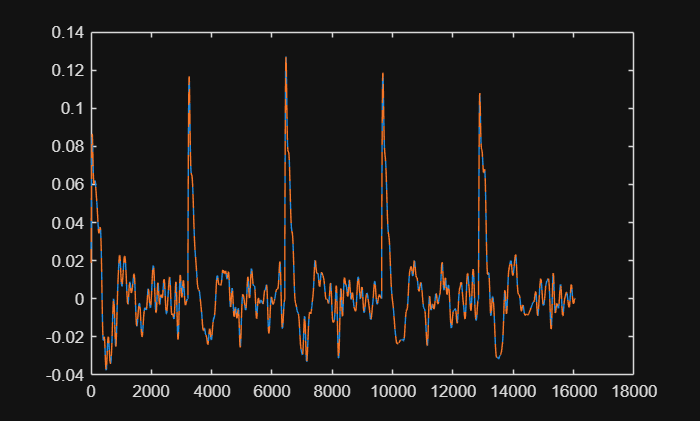

data = Cdd;
labels = Cll;
fs = 2000;

% =========================
% 1. Bandpass Filter
% =========================
data_filt = bandpass_filter(data, fs, 2, 20);

figure;

plot([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)]);
hold on;
plot([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)],'--');

fdat = fft([data_filt(1,:,1),data_filt(1,:,2),data_filt(1,:,3),data_filt(1,:,4),data_filt(1,:,5)],1024);

hold off;

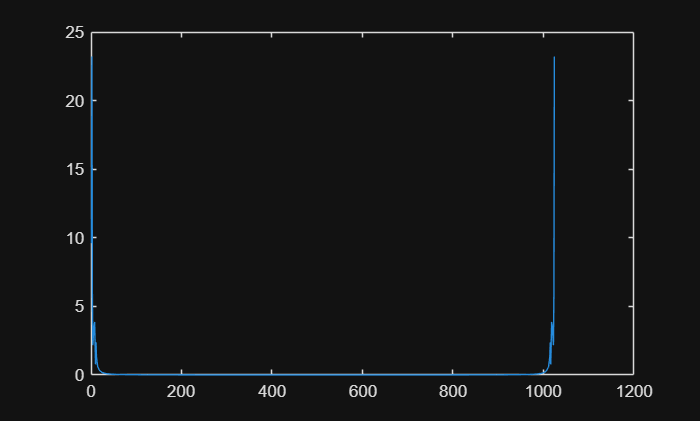

plot(abs(fdat));

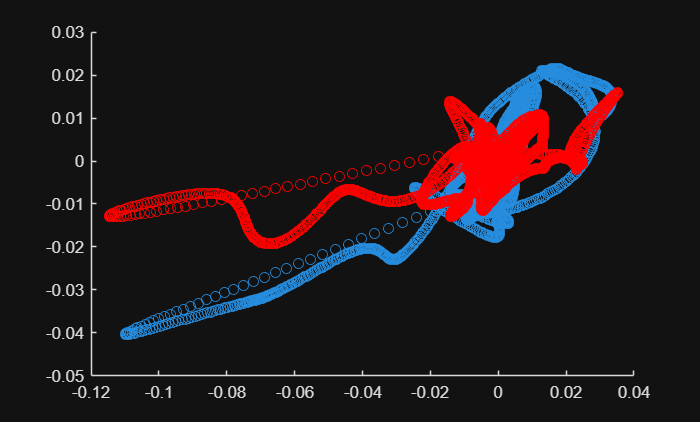

% xlim([0 50])

scatter(data_filt(1,:,10),data_filt(2,:,10));
hold on;
scatter(data_filt(1,:,8),data_filt(2,:,8),'r');
hold off;

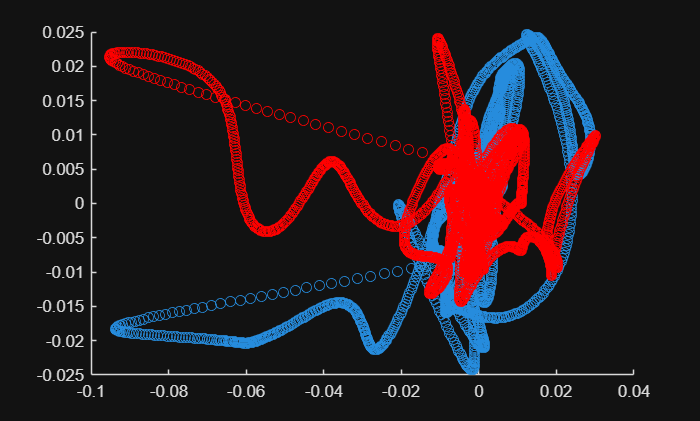


% =========================
% 2. CSP
% =========================
 
W = compute_csp(data_filt, labels,1,-1);
Wright = compute_csp(data_filt, labels,1,0);
Wleft = compute_csp(data_filt, labels,-1,0);

csp_data = W * data_filt(:,:,10);
csp_data2 = W * data_filt(:,:,8);

figure;
scatter(csp_data(1,:),csp_data(2,:));
hold on;
scatter(csp_data2(1,:),csp_data2(2,:),'r');
hold off;

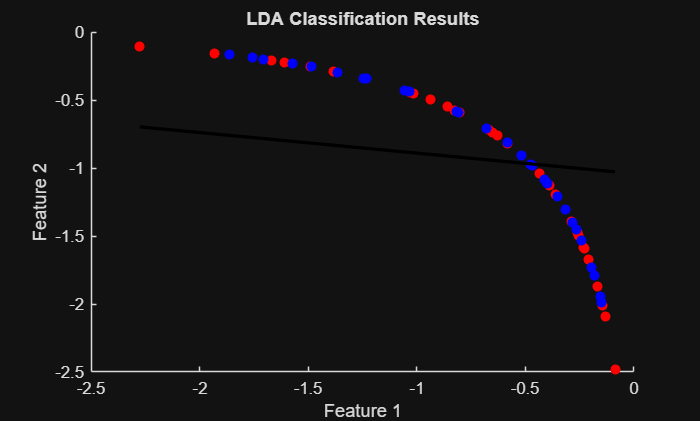

% Select few filters (important)
% m = 2;
% Wcsp = [W(:,1:m), W(:,end-m+1:end)];

% =========================
% 3. Feature Extraction
% =========================
X = extract_features(data_filt, W,Wleft,Wright,2);
% =========================
% 4. Train LDA
% =========================
modelrightleft = myLDA_train(X(:,1:2), labels,1,-1);
modelrightrest = myLDA_train(X(:,5:6), labels,1,0);
modelleftrest = myLDA_train(X(:,3:4), labels,-1,0);

% Visualize predictions
figure;
scatter(X((ll == 1), 5), X((ll == 1),  6), 'r', 'filled');
hold on;
scatter(X((ll == 0),  5), X((ll == 0), 6), 'b', 'filled');
% scatter(X(y_pred == 0, 1), X(y_pred == 0, 2), 'x', 'MarkerEdgeColor', 'k');
% scatter(X(y_pred == 1, 1), X(y_pred == 1, 2), 'x', 'MarkerEdgeColor', 'g');
% Extract parameters
w = modelrightrest.w;
b = modelrightrest.b;

% Create line
x1_vals = linspace(min(X(:,5)), max(X(:,5)), 100);

x2_vals = -(w(1)*x1_vals + b) / w(2);

% Plot decision boundary
plot(x1_vals, x2_vals, 'k-', 'LineWidth', 2);

%legend('Class 0', 'Class 1', 'LDA Boundary');
xlabel('Feature 1');
ylabel('Feature 2');
title('LDA Decision Boundary');
%legend('Class 0', 'Class 1');
title('LDA Classification Results');
hold off;


% =========================
% 5. Predict
% =========================
y_pred = myLDA_predict(X,modelrightleft,modelleftrest,modelrightrest);

acc = mean(y_pred == labels)

acc = 0.4928

disp(['Accuracy: ', num2str(acc)]);

Accuracy: 0.49275
